clear all;
close all;

% Main script
% Tx and Rx are in the far field. Angle of incidence is zero (direction of
% Tx wave normal to the IRS surface).


% system parameters
frequency = 2.4e9; % 2.4 GHz
wavelength = 3e8 / frequency;

distance_tx_to_ris =10; %in m
distance_ris_to_rx = 10;

% Parameters
num_rows = 6;
num_columns = 9;
num_unit_cells = num_rows*num_columns;
unit_cell_spacing = wavelength/2;



% Transmit wave characteristics
transmit_amplitude = 1; % arbitrary units
transmit_phase = 0; % in radians

% Target direction (in degrees) from IRS to the Rx
target_direction = 30; 

% Reflective Intelligent Surface (RIS) phase shifts for beamforming
ris_phase_shifts = zeros(num_rows, num_columns);

% Calculate phase shifts for beamforming
for col = 1:num_columns
    for row = 1:num_rows
        % Calculate phase shift required for beamforming towards target direction
        phase_shift = exp(1j * 2 * pi * sind(target_direction) * sqrt((row - num_rows/2)^2 + (col - num_columns/2)^2) *unit_cell_spacing/wavelength);
      
        % Store the phase shift
        ris_phase_shifts(row, col) = angle(phase_shift); % Phase shift in radians
    end 
end

% Initial wave at the transmitter
wave_amplitude = transmit_amplitude;
wave_phase = transmit_phase; 

% Propagate wave from transmitter to RIS. With normal incidence, equal losses and phase shifts assumed for all paths from Tx to unit cells.
[wave_amplitude, wave_phase] = propagate_wave(wave_amplitude, wave_phase, distance_tx_to_ris, wavelength);

% Reflect off the RIS
reflected_amplitude = zeros(num_rows, num_columns);
reflected_phase = zeros(num_rows, num_columns);

for col = 1:num_columns
    for row = 1:num_rows
        % Each unit cell reflects the wave with its calculated phase shift
        reflected_amplitude(row, col) = wave_amplitude;
        reflected_phase(row, col) = mod(wave_phase + ris_phase_shifts(row, col), 2 * pi);
    end
end

% Combine reflected waves from all unit cells. This is to calculate the
% received signal in the target direction in the absence of IRS is a simple
% plane surface introducing zero phase shift.

combined_signal = sum(reflected_amplitude(:).*exp(1j*reflected_phase(:)));
combined_amplitude = abs(combined_signal);
combined_phase = angle(combined_signal);

% Propagate wave from RIS to receiver
[final_amplitude, final_phase] = propagate_wave(combined_amplitude, combined_phase, distance_ris_to_rx, wavelength);
final_phase = mod(final_phase, 2 * pi); % Ensure final phase is within [0, 2*pi]

% Output results
disp('Final received wave characteristics with zero phase shifts by IRS:');

Final received wave characteristics with zero phase shifts by IRS:


disp(['Amplitude: ', num2str(final_amplitude)]);

Amplitude: 4.6885e-06


disp(['Phase (radians): ', num2str(final_phase)]);

Phase (radians): 4.9716


disp(['Phase (degrees): ', num2str(rad2deg(final_phase))]);

Phase (degrees): 284.8521


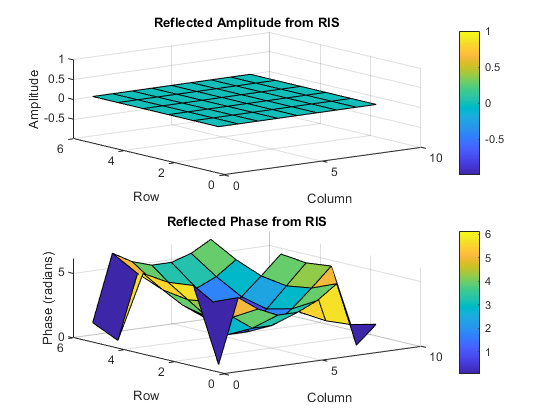


% Plotting for visualization using 3D surface plots
[X, Y] = meshgrid(1:num_columns, 1:num_rows);

figure;
subplot(2, 1, 1);
surf(X, Y, reflected_amplitude);
title('Reflected Amplitude from RIS');
xlabel('Column');
ylabel('Row');
zlabel('Amplitude');
colorbar;

subplot(2, 1, 2);
surf(X, Y, reflected_phase);
title('Reflected Phase from RIS');
xlabel('Column');
ylabel('Row');
zlabel('Phase (radians)');
colorbar;


% combined signal with phase compensation at IRS
combined_signal = sum(reflected_amplitude(:));
combined_amplitude = abs(combined_signal);
combined_phase = angle(combined_signal);

% Propagate wave from RIS to receiver
[final_amplitude, final_phase] = propagate_wave(combined_amplitude, combined_phase, distance_ris_to_rx, wavelength);
final_phase = mod(final_phase, 2 * pi); % Ensure final phase is within [0, 2*pi]

% Output results
disp('Final received wave characteristics with phase compensation at IRS:');

Final received wave characteristics with phase compensation at IRS:


disp(['Amplitude: ', num2str(final_amplitude)]);

Amplitude: 5.3431e-05


disp(['Phase (radians): ', num2str(final_phase)]);

Phase (radians): 0


disp(['Phase (degrees): ', num2str(rad2deg(final_phase))]);

Phase (degrees): 0


disp(['IRS phase shifts (degrees):']);

IRS phase shifts (degrees):


disp([num2str(rad2deg(ris_phase_shifts))]);

 2.801599     -71.85941          -135     -174.4602     -174.4602          -135     -71.85941      2.801599       83.1986
-32.39505     -117.6676      162.2498      100.6231      100.6231      162.2498     -117.6676     -32.39505       54.8795
      -45          -135           135            45            45           135          -135           -45            45
-32.39505     -117.6676      162.2498      100.6231      100.6231      162.2498     -117.6676     -32.39505       54.8795
 2.801599     -71.85941          -135     -174.4602     -174.4602          -135     -71.85941      2.801599       83.1986
  54.8795     -8.538765     -58.13082     -86.27569     -86.27569     -58.13082     -8.538765       54.8795      126.7494


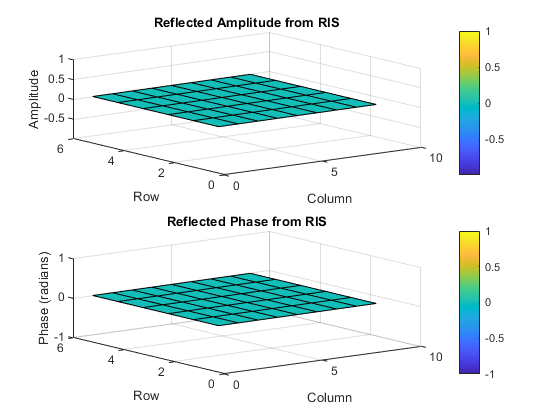


figure;
subplot(2, 1, 1);
surf(X, Y, reflected_amplitude);
title('Reflected Amplitude from RIS');
xlabel('Column');
ylabel('Row');
zlabel('Amplitude');
colorbar;

subplot(2, 1, 2);
surf(X, Y, reflected_phase-reflected_phase);
title('Reflected Phase from RIS');
xlabel('Column');
ylabel('Row');
zlabel('Phase (radians)');
colorbar;



% Function definitions must be at the end of the file
% we're on github

function [amplitude, phase] = propagate_wave(amplitude, phase, distance, wavelength)
    % Free space path loss model
    path_loss = (wavelength / (4 * pi * distance))^2; 
    amplitude = amplitude * sqrt(path_loss);
    phase = phase + (2 * pi * distance / wavelength); 
end
